Load the Apple Watch dataset into the variable "data" using the Turbo drive path

temp = load('Toyota/Data/Processed/BigIdeasLab_HRSmartwatch/hrdata.mat');
data = temp.hrdata;

Create a simple scatterplot of the ECG and Apple Watch heart rates

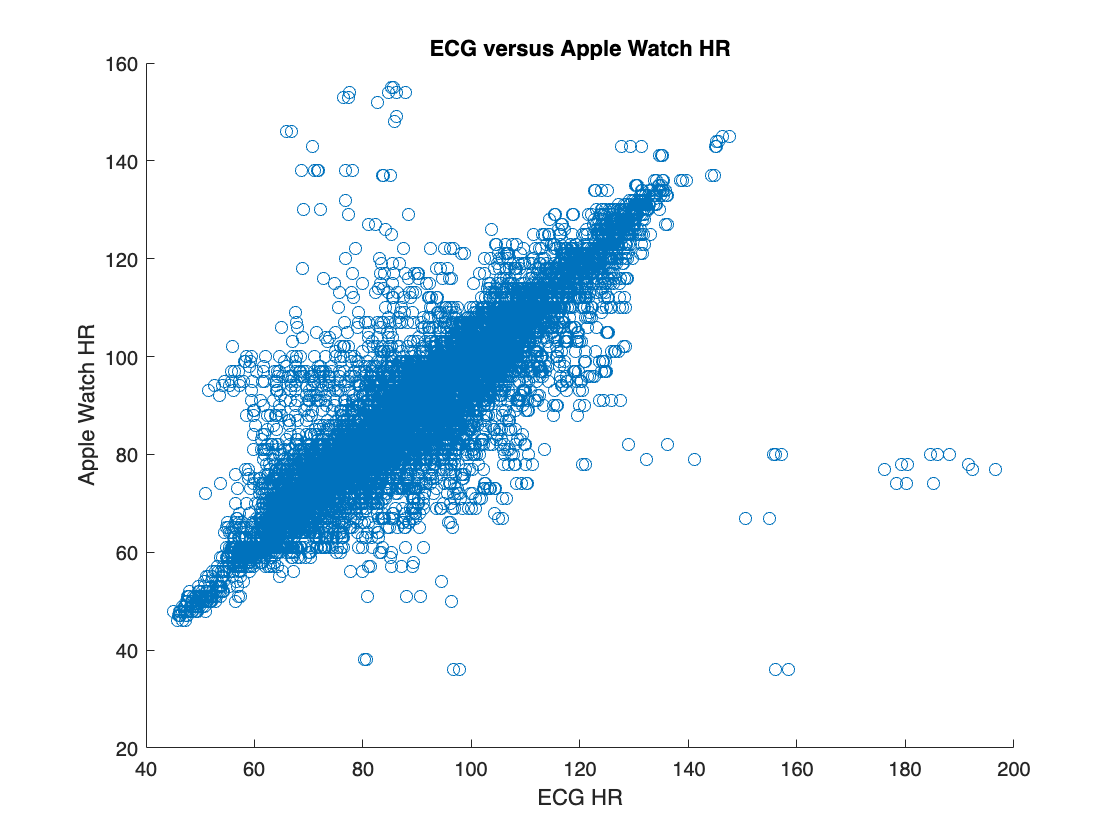

scatter(data.ECG, data.AppleWatch)
title('ECG versus Apple Watch HR')
xlabel('ECG HR')
ylabel('Apple Watch HR')

Plot the trend of Apple Watch heart rate over time.

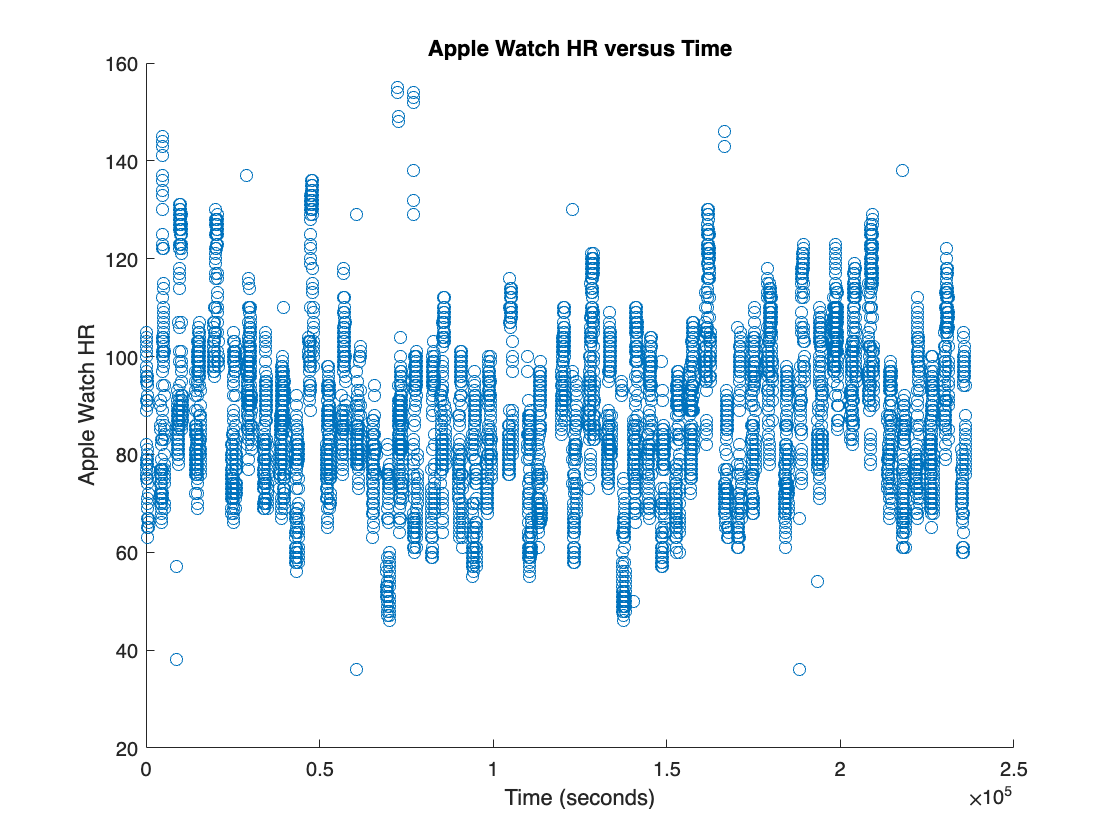

scatter([1:size(data,1)], data.AppleWatch)
title('Apple Watch HR versus Time')
xlabel('Time (seconds)')
ylabel('Apple Watch HR')

Plot the trend of Apple Watch heart rate for patient 19-006

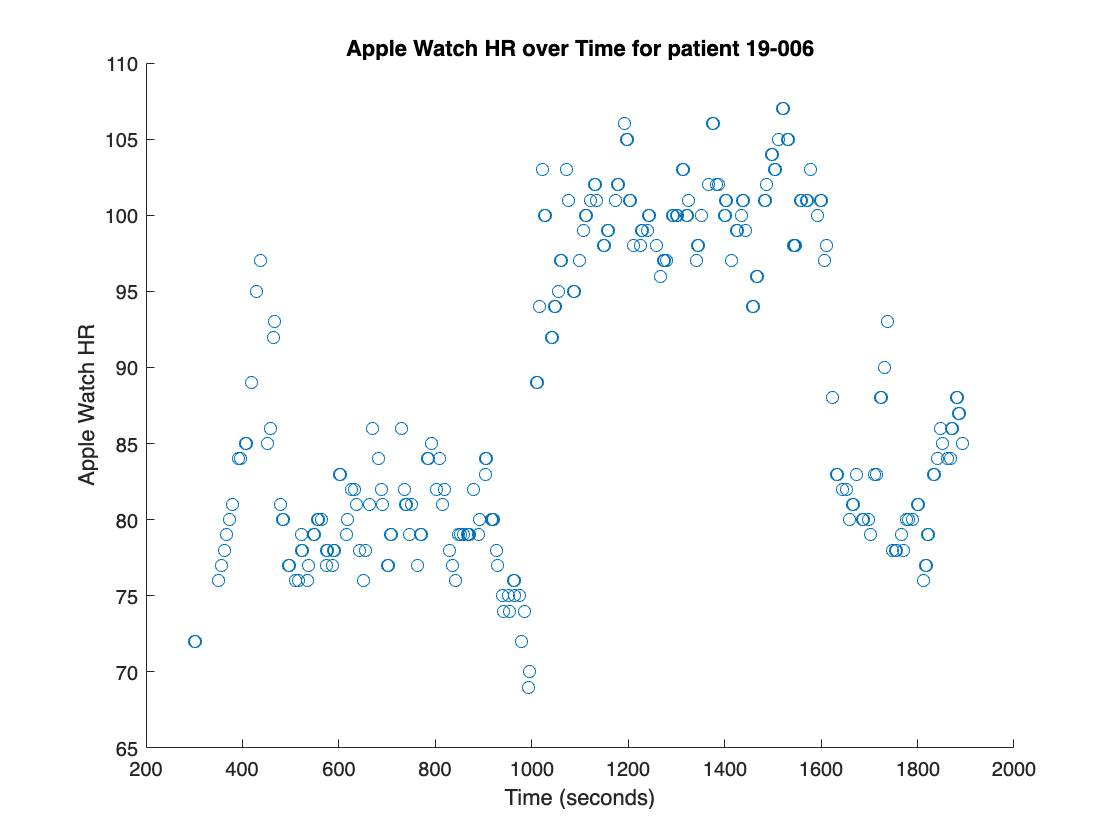

id = '19-006';
patient_data = data(data.ID == id, :);
scatter([1:size(patient_data,1)], patient_data.AppleWatch)
title('Apple Watch HR over Time for patient 19-006')
xlabel('Time (seconds)')
ylabel('Apple Watch HR')

Color by activity type

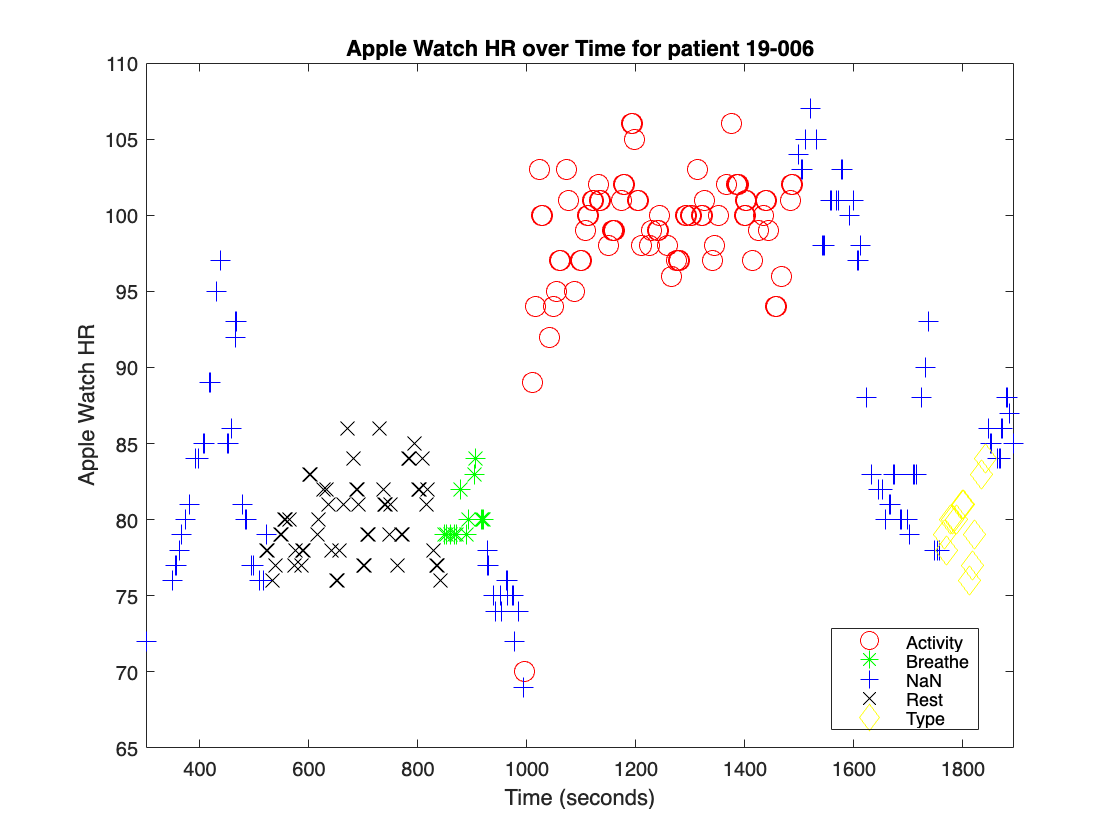

id = '19-006';
patient_data = data(data.ID == id, :);
gscatter([1:size(patient_data,1)], patient_data.AppleWatch, patient_data.Activity, 'rgbky', 'o*+xd', [10 10 10 10 10], 'on')
title('Apple Watch HR over Time for patient 19-006')
xlabel('Time (seconds)')
ylabel('Apple Watch HR')
legend('Location', 'best')
xlim('tight')

TASK 1: Create scatterplot of ECG heart rate over time, colored by activity type, for patient 19-006.

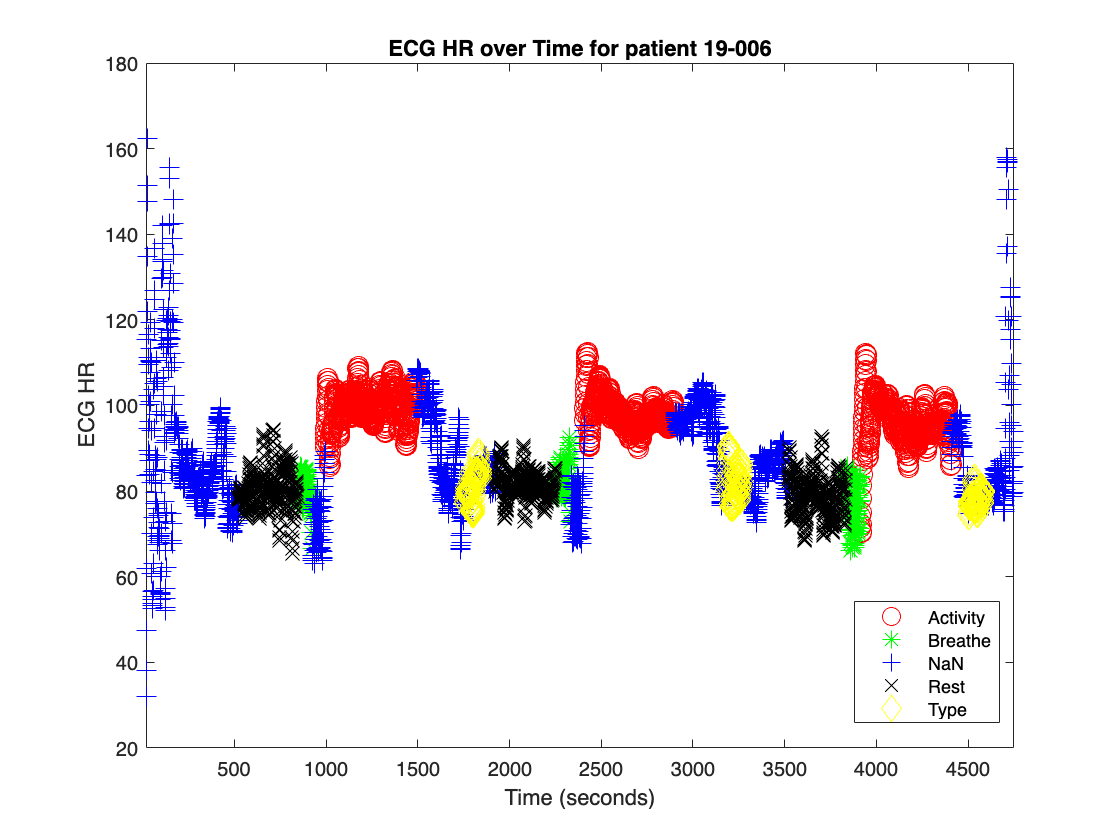

id = '19-006';
patient_data = data(data.ID == id, :);
gscatter([1:size(patient_data,1)], patient_data.ECG, patient_data.Activity, 'rgbky', 'o*+xd', [10 10 10 10 10], 'on')
title('ECG HR over Time for patient 19-006')
xlabel('Time (seconds)')
ylabel('ECG HR')
legend('Location', 'best')
xlim('tight')

Compare ECG HR plot to Apple Watch HR plot. What is different between the two plots? Why is the ECG HR plot different (the answer can be found in the paper).

TASK 2: Create scatterplot of both Apple Watch heart rate and ECG heart rate over time for patient 19-006. Put both trends in the same scatterplot.

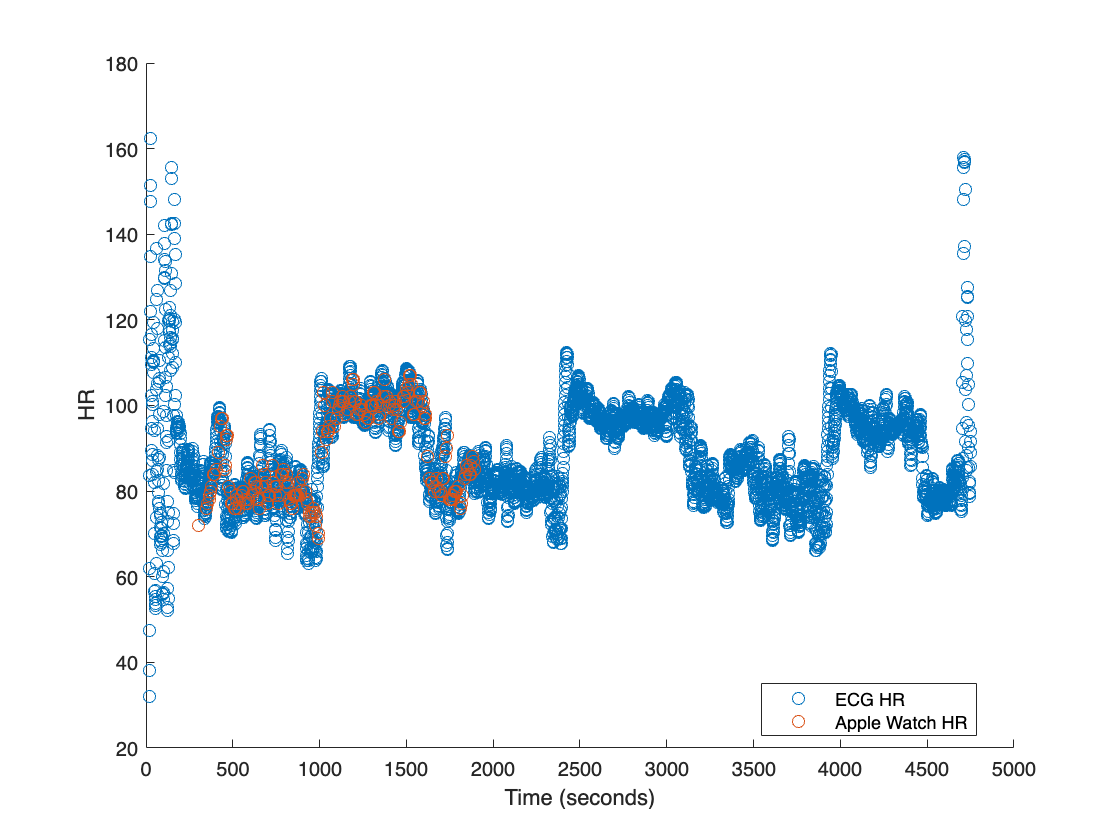

id = '19-006';
patient_data = data(data.ID == id, :);
figure; hold on;
scatter([1:size(patient_data,1)], patient_data.ECG)
scatter([1:size(patient_data,1)], patient_data.AppleWatch)
legend('ECG HR', 'Apple Watch HR', 'Location', 'best')
xlabel('Time (seconds)')
ylabel('HR')

Find the time range where Apple Watch HR data was collected for patient 19-006.

id = '19-006';
patient_data = data(data.ID == id, :);
applewatch_notnan = ~isnan(patient_data.AppleWatch);
applewatch_notnan_index = find(applewatch_notnan);
disp(applewatch_notnan_index)

         301
         302
         350
         356
         357
         363
         367
         373
         380
         391
         392
         397
         406
         407
         408
         418
         419
         430
         437
         438
         451
         452
         458
         465
         466
         467
         478
         484
         485
         486
         495
         498
         509
         510
         516
         522
         523
         524
         534
         538
         548
         549
         555
         556
         557
         564
         574
         575
         576
         586
         587
         589
         590
         601
         602
         603
         615
         617
         618
         627
         632
         636
         642
         651
         652
         656
         663
         664
         670
         682
         688
         689
         691
         701
         702
         708
         709

start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];
disp('the start and end seconds of Apple Watch HR recording are: ')

the start and end seconds of Apple Watch HR recording are: 


disp(start_end_range)

         301        1894



TASK 3: Create scatterplot of both Apple Watch heart rate and ECG heart rate over time for patient 19-006. Plot only over the times when Apple Watch heart rate data is available.

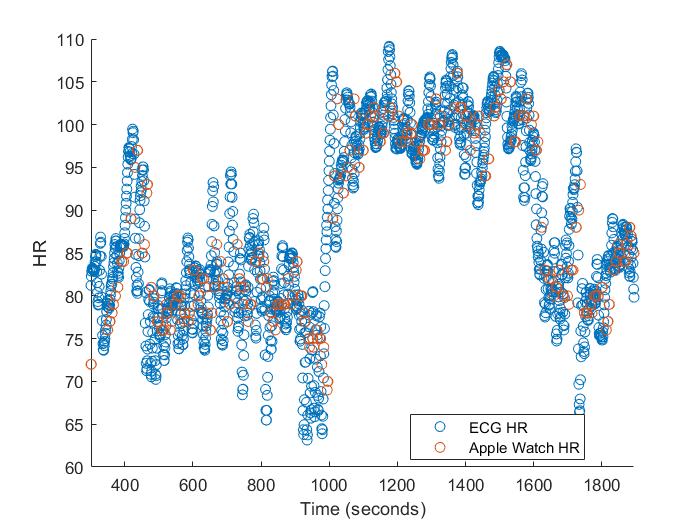

id = '19-006';
patient_data = data(data.ID == id, :);
applewatch_notnan = ~isnan(patient_data.AppleWatch);
applewatch_notnan_index = find(applewatch_notnan);
start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];

figure; hold on;
scatter([1:size(patient_data,1)], patient_data.ECG)
scatter([1:size(patient_data,1)], patient_data.AppleWatch)
legend('ECG HR', 'Apple Watch HR', 'Location', 'best')
xlabel('Time (seconds)')
ylabel('HR')
xlim(start_end_range)

TASK 4: Plot ECG HR as a line plot instead for better comparison.

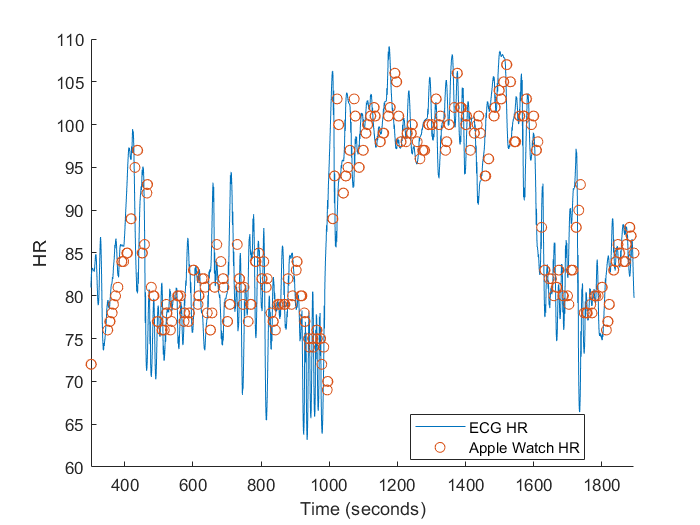

id = '19-006';
patient_data = data(data.ID == id, :);
applewatch_notnan = ~isnan(patient_data.AppleWatch);
applewatch_notnan_index = find(applewatch_notnan);
start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];

figure; hold on;
plot([1:size(patient_data,1)], patient_data.ECG)
scatter([1:size(patient_data,1)], patient_data.AppleWatch)
legend('ECG HR', 'Apple Watch HR', 'Location', 'best')
xlabel('Time (seconds)')
ylabel('HR')
xlim(start_end_range)

TASK 5: Calculate sampling rate of Apple Watch HR values for patient 19-006. To do this, find the number of Apple Watch samples (non-nan data points) for patient 19-006. Divide this number by the total number of seconds during which Apple Watch heart rate is available (ending range - starting range).

From the paper, we know that each row of the dataset is 1 second. ECG has a default sampling frequency of 1 Hz (sampling rate of 1 sample per second).

id = '19-006';
patient_data = data(data.ID == id, :);
applewatch_notnan = ~isnan(patient_data.AppleWatch);
applewatch_notnan_index = find(applewatch_notnan);
start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];

applewatch_notnan_number = length(applewatch_notnan_index);
applewatch_total_seconds = start_end_range(2) - start_end_range(1);

applewatch_sampling_rate = applewatch_notnan_number / applewatch_total_seconds;
disp('apple watch sampling rate: ')

apple watch sampling rate: 


disp([num2str(applewatch_sampling_rate) ' samples per second'])

0.19837 samples per second


disp('apple watch sampling period ')

apple watch sampling period 


disp('(average time interval for Apple Watch to take a heart rate measurement):')

(average time interval for Apple Watch to take a heart rate measurement):


disp([num2str(1/applewatch_sampling_rate) ' seconds'])

5.0411 seconds


Compare MSE of Apple Watch HR vs ECG HR before and after interpolation methods.

% directional and absolute MSE without interpolation
matched = data((~isnan(data.ECG) & ~isnan(data.AppleWatch)), :);
MDE = mean(matched.ECG - matched.AppleWatch);
MAE = mean(abs(matched.ECG - matched.AppleWatch));
disp(MDE)  % mean directional error

    0.3186




disp(MAE) % mean absolute error

    5.4191



Sampling rate for each patient (no interpolation)

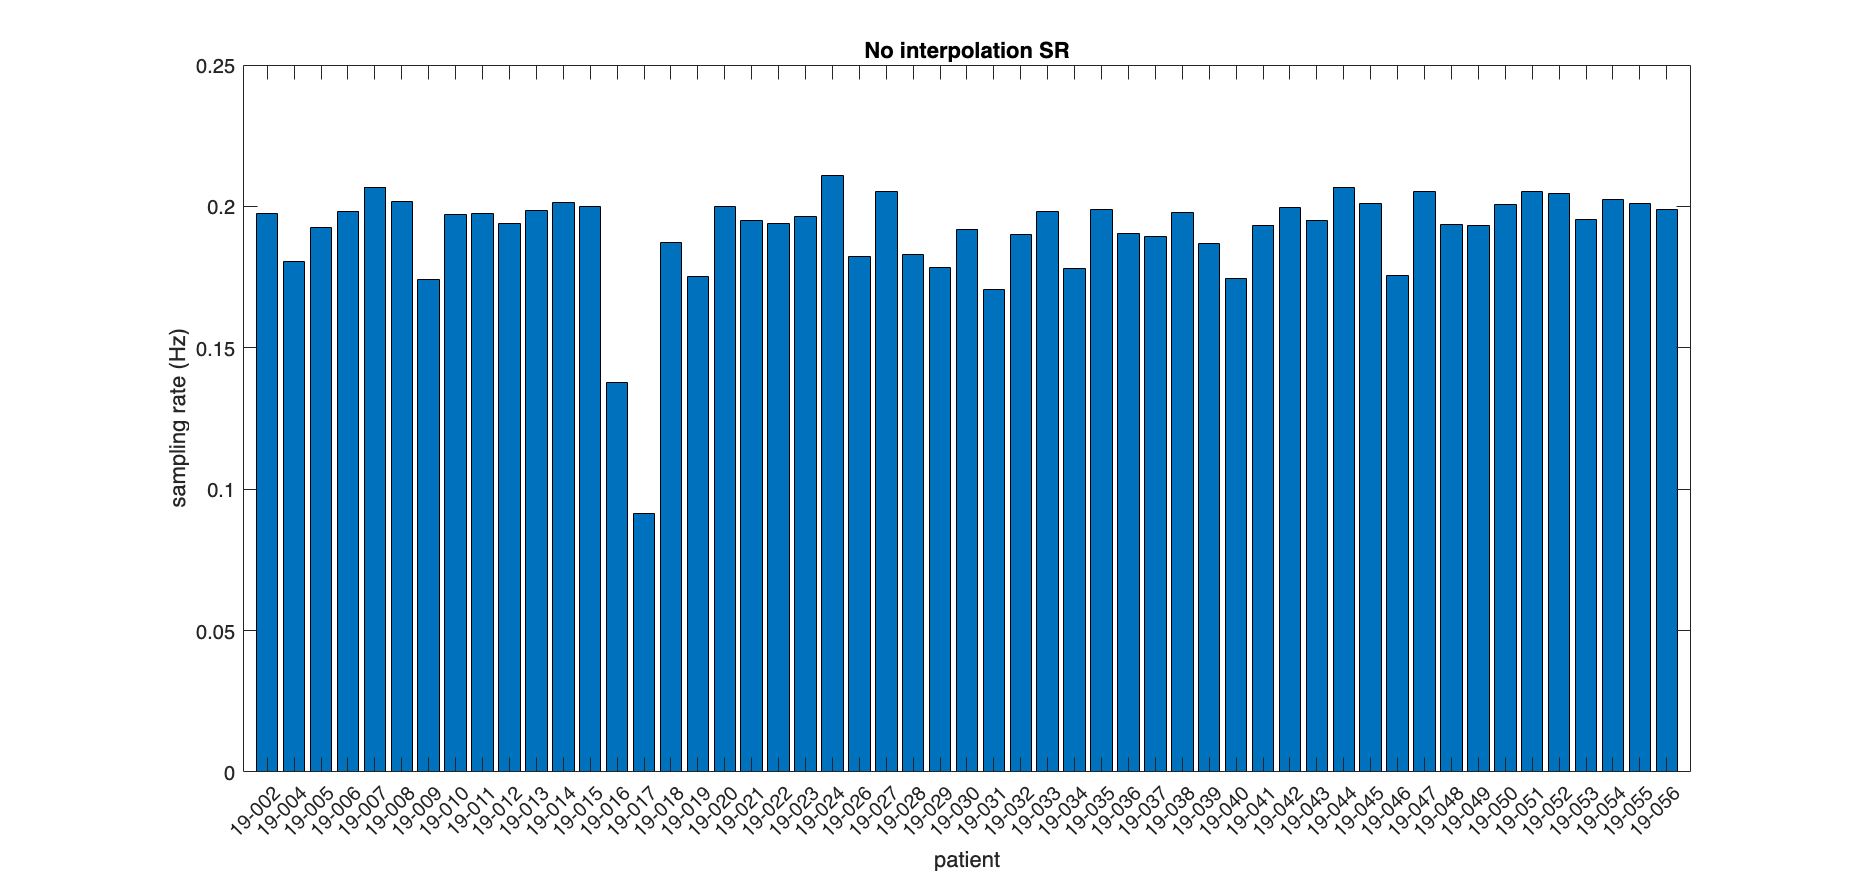

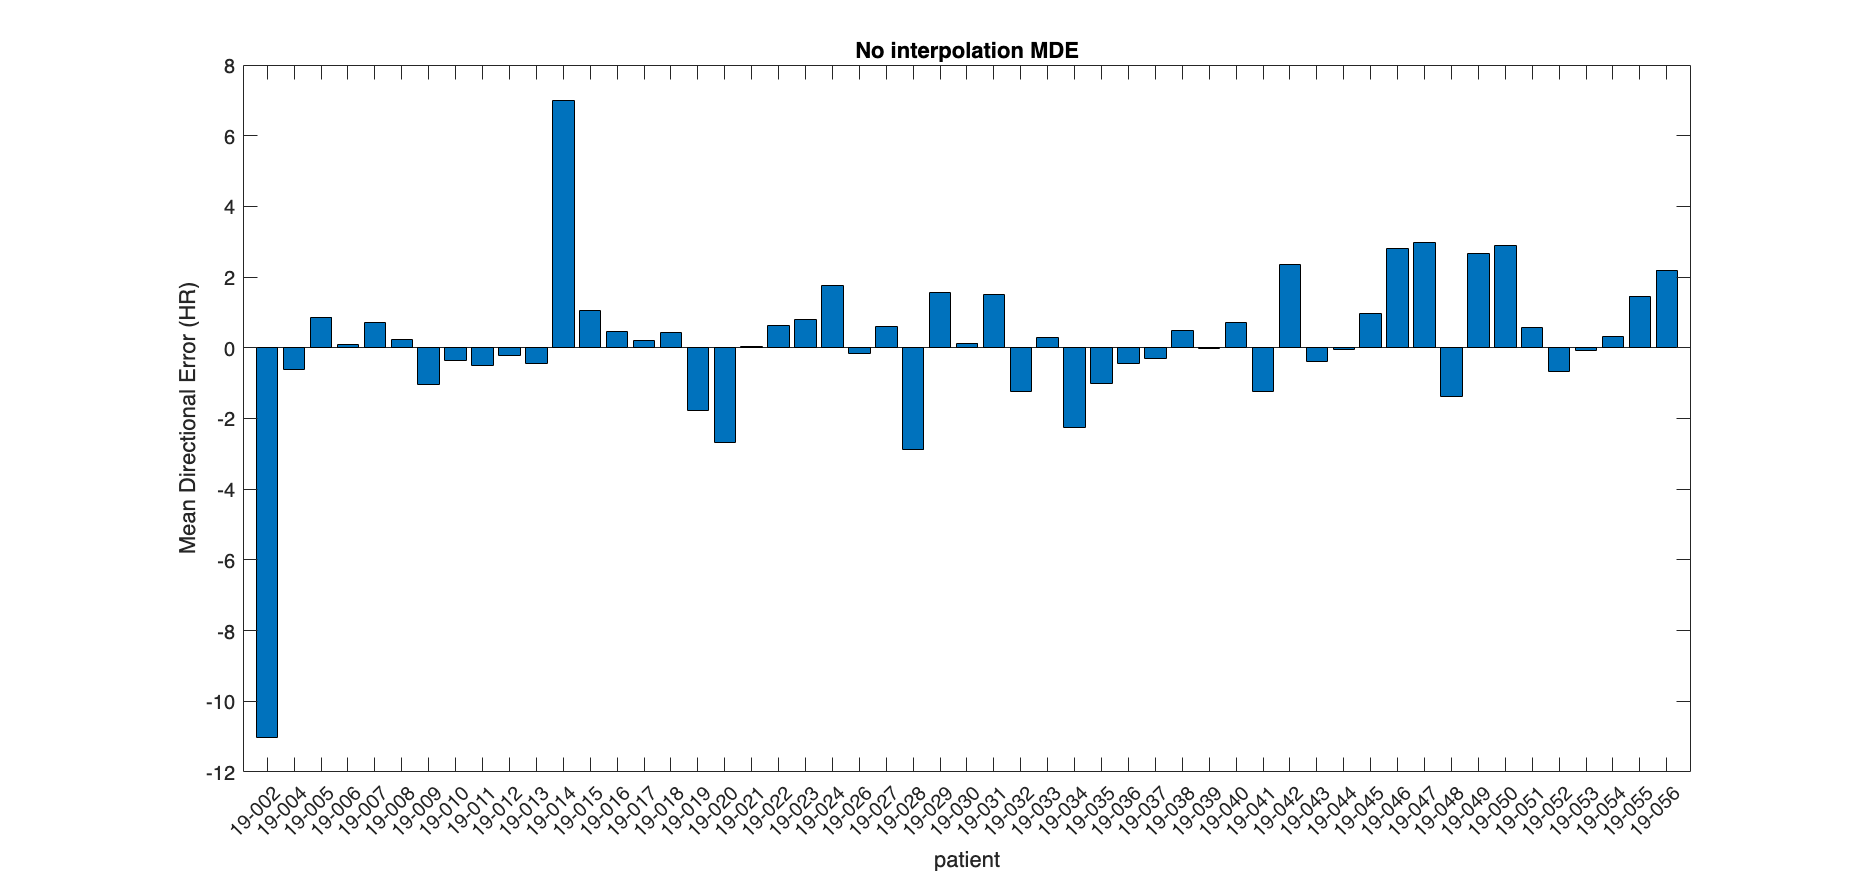

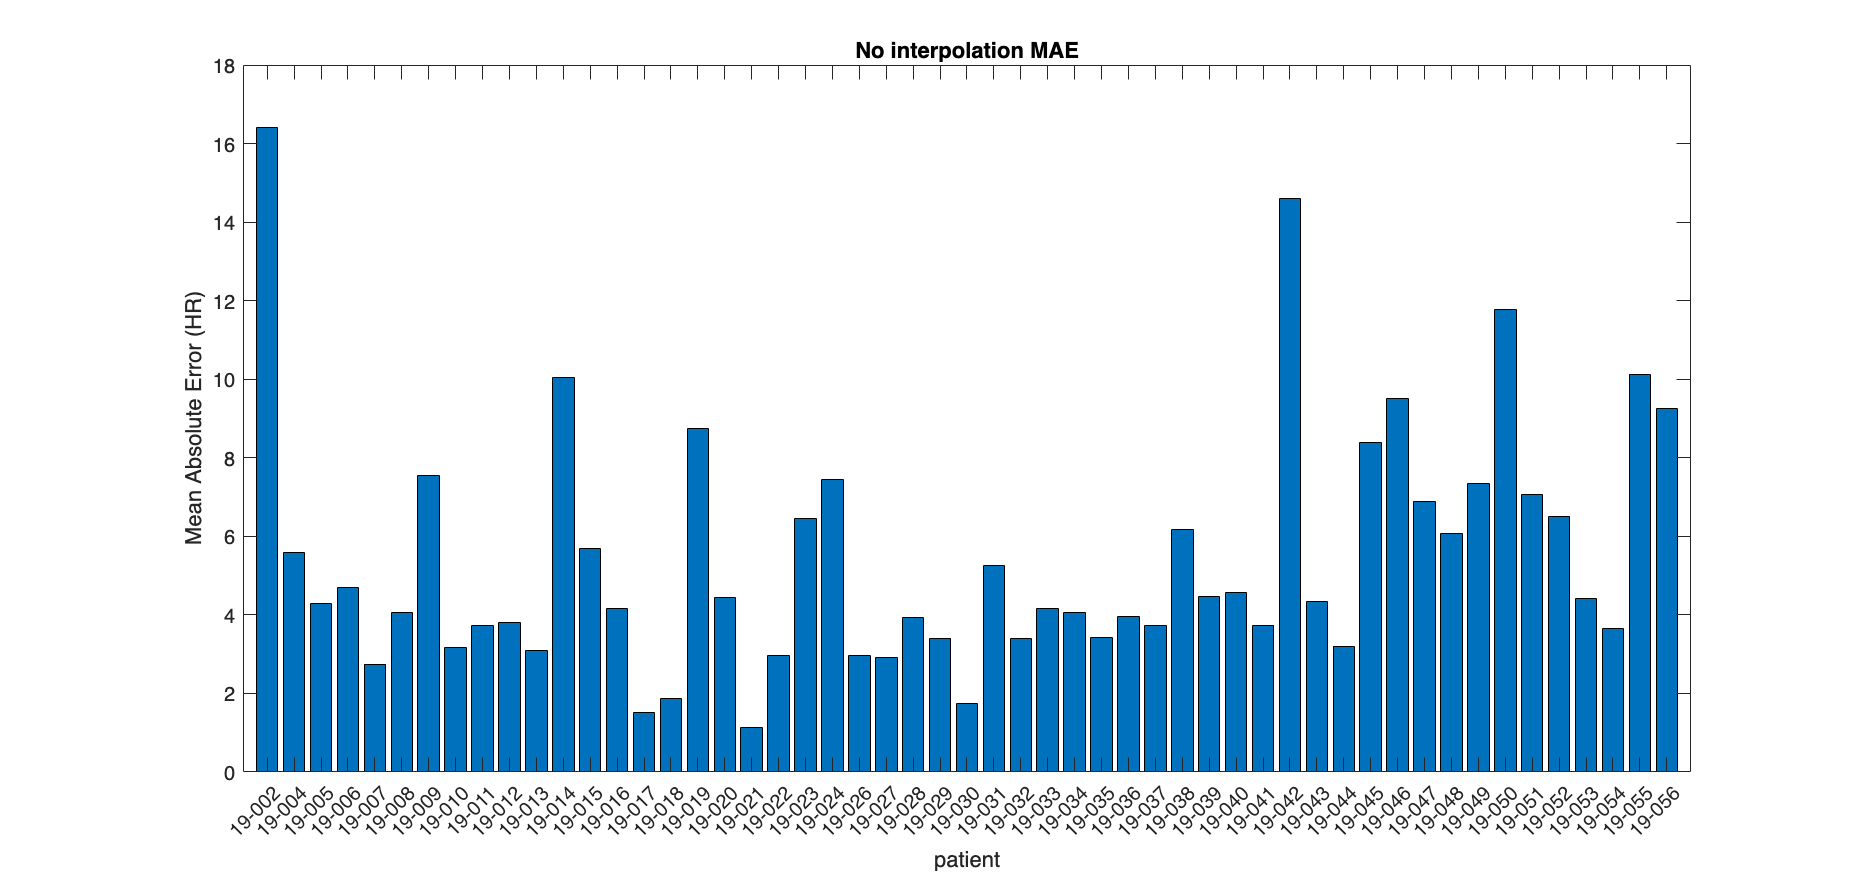

mplot_AW_stats(data, 'No interpolation')

After interpolation

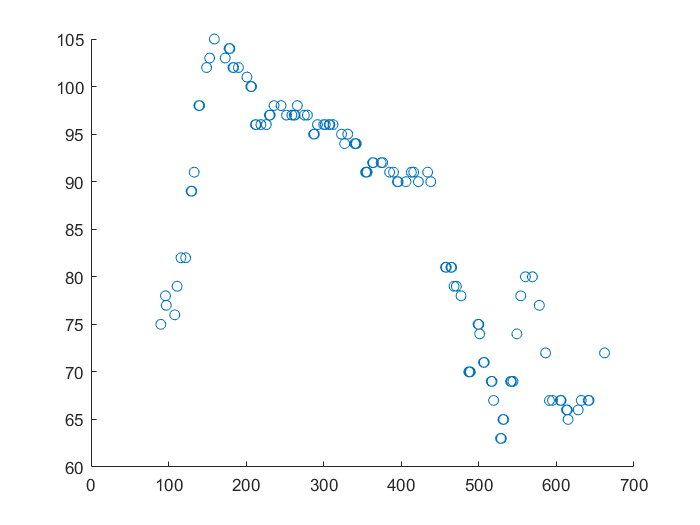

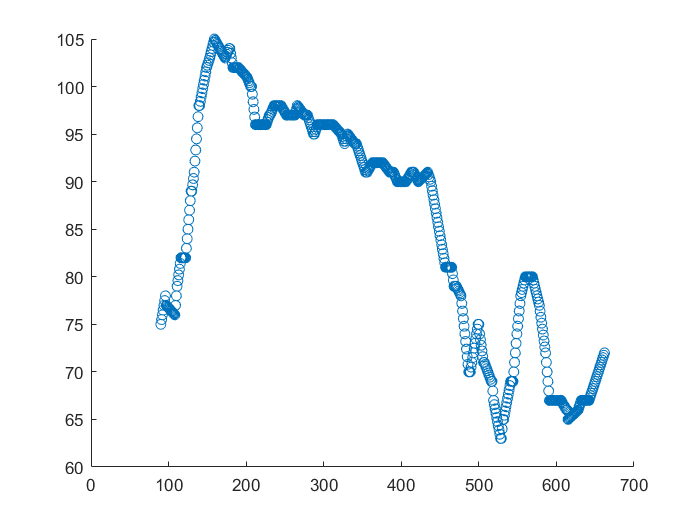

% sampling rate statistics for each patient (after interpolation)
interpolated_data = data;

pt_id = unique(data.ID);
for pti = 1:length(pt_id)
    patient_data = data(data.ID == pt_id(pti), :);
    applewatch_notnan = ~isnan(patient_data.ECG) & ~isnan(patient_data.AppleWatch);
    applewatch_notnan_index = find(applewatch_notnan);
    start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];
    
    xin = applewatch_notnan_index;
    yin = patient_data.AppleWatch(xin);
    xout = [start_end_range(1):start_end_range(2)];
    
    % this is the function that interpolates the data
    % try different interpolation methods
    yout = interp1(xin, yin, xout, 'linear');
    
    patient_data.AppleWatch(xout) = yout;
    interpolated_data(data.ID == pt_id(pti), :) = patient_data;
    
    if pti == 1
        figure;
        scatter(xin, yin);
        figure;
        scatter(xout, yout);
    end
end

% directional and absolute MSE with interpolation
matched = interpolated_data((~isnan(interpolated_data.ECG) & ~isnan(interpolated_data.AppleWatch)), :);
MDE = mean(matched.ECG - matched.AppleWatch);
MAE = mean(abs(matched.ECG - matched.AppleWatch));
disp(MDE)  % mean directional error

    0.2529



disp(MAE) % mean absolute error

    5.7462



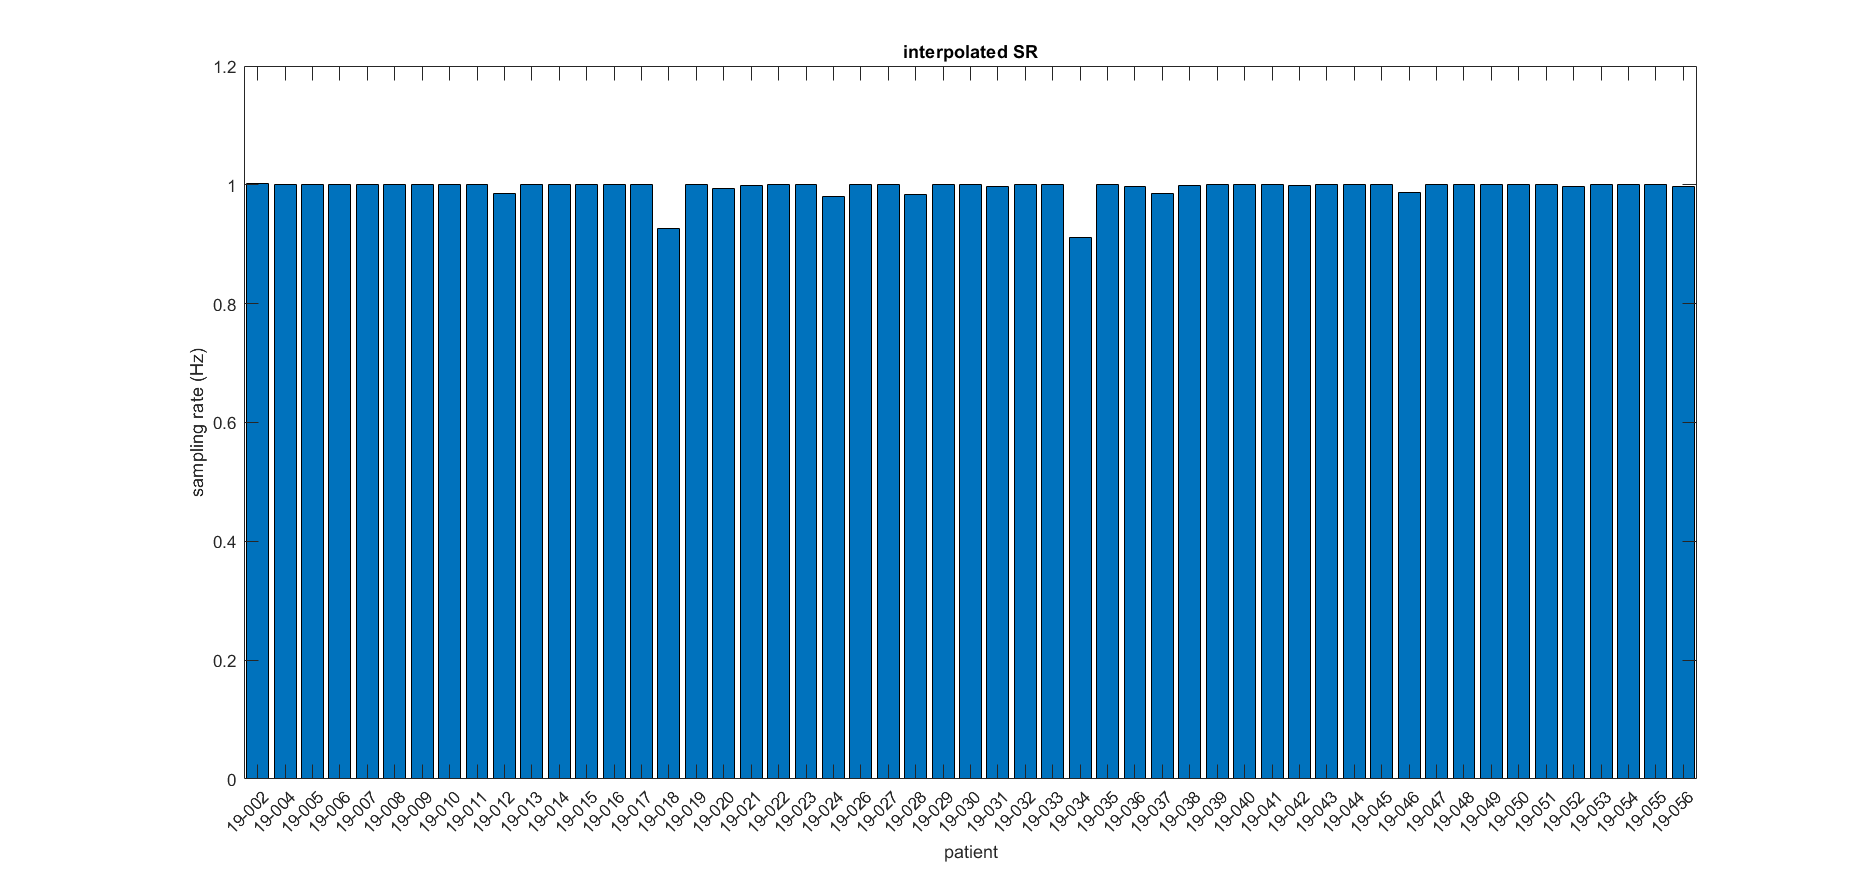

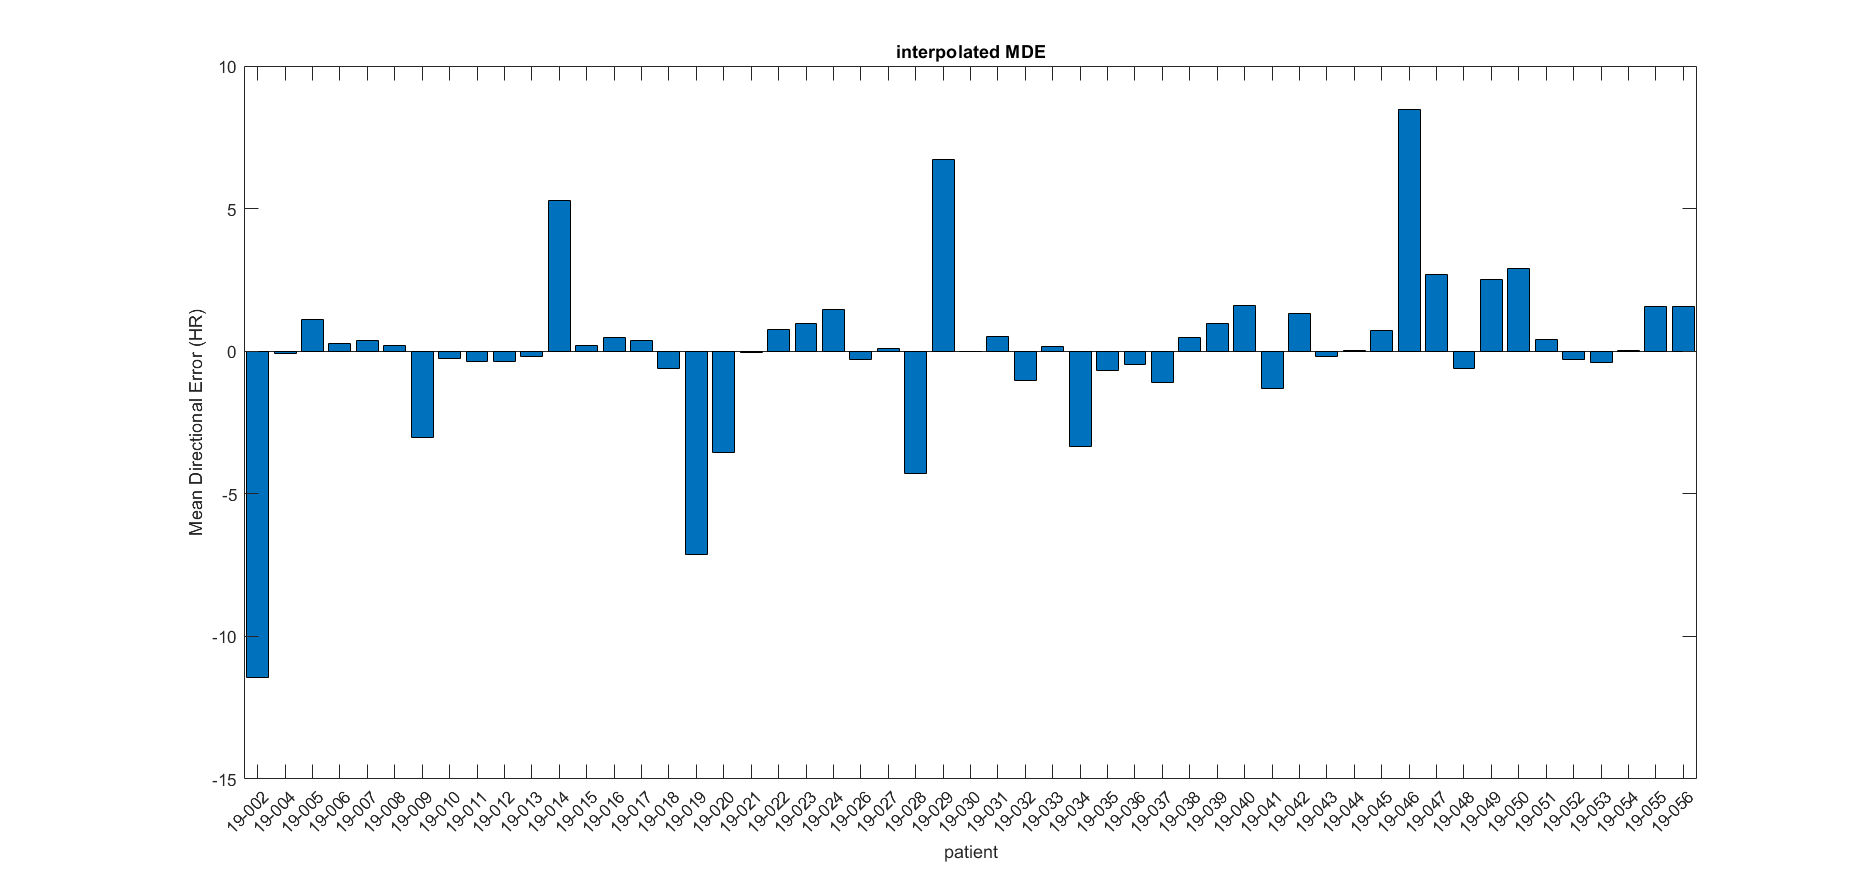

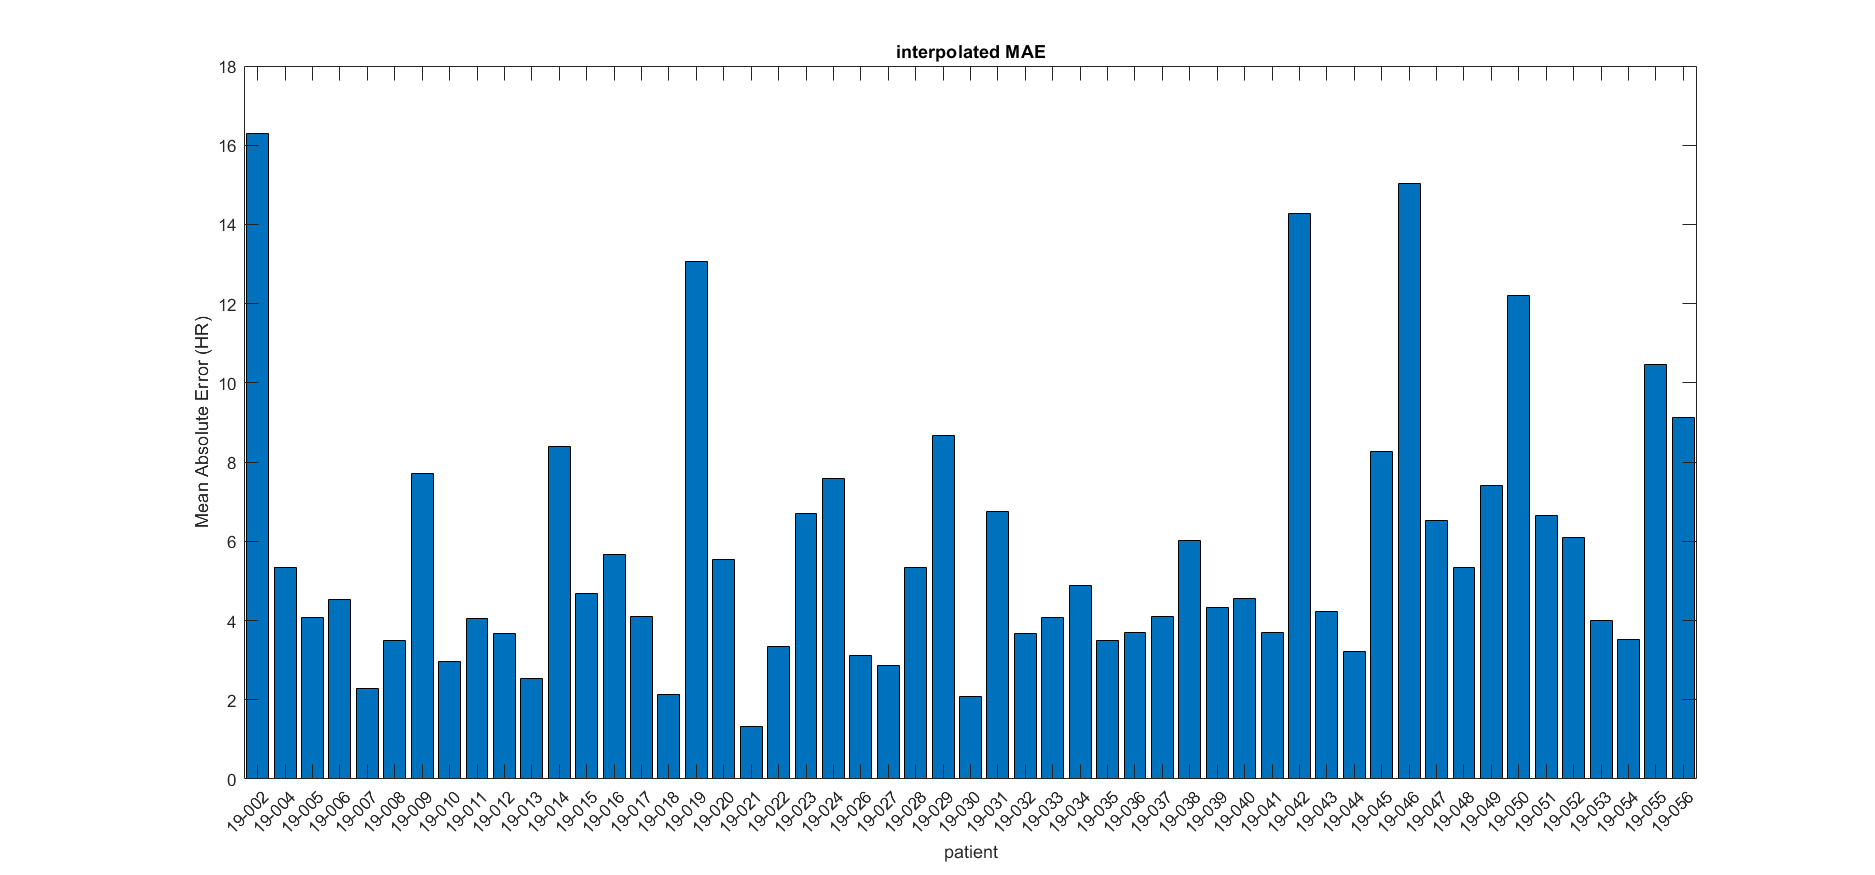

plot_AW_stats(interpolated_data, 'interpolated')

TASK 6: Compare the patient sampling rates before interpolation and after interpolation. What changed?

The sampling rate increased from an average around 0.15 to an average of 1 for the sampling rate after interpolation.

TASK 7: Compare the MDE and MAE before and after interpolation. What do you notice? Does interpolation have any effect on mean error between Apple Watch and ECG heart rate?

TASK 8: Try different interpolation methods using the "interp1" function. Do they change the results?

Function for plotting apple watch bar graphs

function plot_AW_stats(data, type)
    pt_id = unique(data.ID);
    pt_stats = struct([]);
    pt_me = [];
    for pti = 1:length(pt_id)
        patient_data = data(data.ID == pt_id(pti), :);
        applewatch_notnan = ~isnan(patient_data.ECG) & ~isnan(patient_data.AppleWatch);
        applewatch_notnan_index = find(applewatch_notnan);
        start_end_range = [min(applewatch_notnan_index), max(applewatch_notnan_index)];
        
        applewatch_notnan_number = length(applewatch_notnan_index);
        applewatch_total_seconds = start_end_range(2) - start_end_range(1);
        applewatch_sampling_rate = applewatch_notnan_number / applewatch_total_seconds;
        
        pt_stat = struct();
        pt_stat.id = pt_id(pti);
        pt_stat.data = patient_data;
        pt_stat.range = start_end_range;
        pt_stat.rate = applewatch_sampling_rate;
        pt_stats = [pt_stats; pt_stat];
        
        matched = patient_data(applewatch_notnan,:);
        MDE = mean(matched.ECG - matched.AppleWatch);
        MAE = mean(abs(matched.ECG - matched.AppleWatch));
        pt_me = [pt_me; [MDE MAE]];
    end
    
    figure; bar(pt_id, [pt_stats.rate]);
    title([type ' SR'])
    xlabel('patient')
    ylabel('sampling rate (Hz)')
    set(gcf, 'position', [0,0,1500,700]);
    
    figure; bar(pt_id, pt_me(:,1));
    title([type ' MDE'])
    xlabel('patient')
    ylabel('Mean Directional Error (HR)')
    set(gcf, 'position', [0,0,1500,700]);
    
    figure; bar(pt_id, pt_me(:,2));
    title([type ' MAE'])
    xlabel('patient')
    ylabel('Mean Absolute Error (HR)')
    set(gcf, 'position', [0,0,1500,700]);
end